cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

cd("../data-engineering")
load("../../temp-data/participant_list.mat")
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Performance Metric Computation

metric_type = "trmse";
metric_task = "none";
y = compute_performance_table(participant_array, metric_type, metric_task);

Participant 01: P05
	Condition: par
		Task: ml
			Trial 01	Co-Activation:0.429	 Differentiation:0.144
			Trial 02	Co-Activation:0.470	 Differentiation:0.252
			Trial 03	Co-Activation:0.470	 Differentiation:0.287
			Trial 04	Co-Activation:0.417	 Differentiation:0.329
			Trial 05	Co-Activation:0.418	 Differentiation:0.315
			Trial 06	Co-Activation:0.457	 Differentiation:0.172
			Trial 07	Co-Activation:0.394	 Differentiation:0.231
			Trial 08	Co-Activation:0.385	 Differentiation:0.147
			Trial 09	Co-Activation:0.343	 Differentiation:0.285
		Task: hl
			Trial 01	Co-Activation:0.444	 Differentiation:0.110
			Trial 02	Co-Activation:0.322	 Differentiation:0.112
			Trial 03	Co-Activation:0.319	 Differentiation:0.144
			Trial 04	Co-Activation:0.245	 Differentiation:0.120
			Trial 05	Co-Activation:0.246	 Differentiation:0.179
			Trial 06	Co-Activation:0.274	 Differentiation:0.045
			Trial 07	Co-Activation:0.273	 Differentiation:0.057
			Trial 08	Co-Activation:0.380	 Differentiation:0.140
			Tria

## Statistical Analysis

### Step 0. Structure Data Matrix

Between-factors (Hand Condition) are specified in the rows of `y_between`. Within-subject factors (Task, Gesture Type, and Trial Count) are specified in `y_within` and they are the labels for each column of `y_between`.

y_between = y

y_between = 15×55 table
    b_condition      y_1        y_2        y_3        y_4        y_5        y_6        y_7        y_8        y_9        y_10        y_11        y_12       y_13        y_14       y_15       y_16       y_17       y_18       y_19       y_20       y_21       y_22       y_23       y_24       y_25       y_26       y_27       y_28       y_29       y_30        y_31       y_32        y_33        

w_task = [repmat("Machine Learning", 18,1); repmat("Human Learning", 18,1); repmat("Co-Adaptive Learning", 18, 1)];
w_gesture = repmat([repmat("Co-Activation", 9,1); repmat("Differentiation", 9,1)], 3,1);
w_trial = repmat((1:9)', 6,1);
y_within = table(w_task, w_gesture, w_trial)

y_within = 54×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Co-Activation"         5   
    "Machine Learning"    "Co-Activation"         6   
    "Machine Learning"    "Co-Activation"         7   
    "Machine Learning"    "Co-Activation"         8   
    "Machine Learning"    "Co-Activation"         9   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Machine Learning"    "Differentiation"       

### Step 1. Visualize Raw Data in Panels

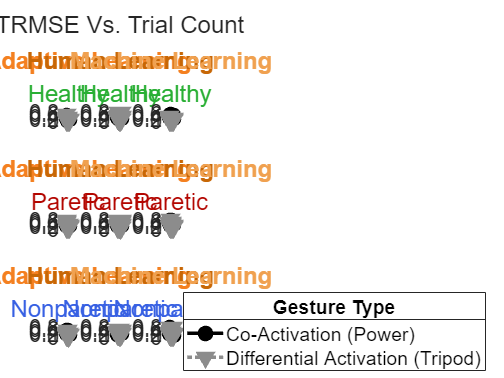

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["hlt","par", "xpar"]
    y_cond = y_between(y_between.b_condition==cond,2:end);
    for task = ["Co-Adaptive Learning", "Human Learning", "Machine Learning"]
        y_coact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)",repmat("",1,4), "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([0, 0.8])
xlim([0 10])
title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

save("..\..\results\trmse_raw.mat", "y_between", "y_within")

fig_h = figure;
set(fig_h, 'Renderer', 'painters');
set(fig_h, "Units","centimeters", "Position", [5, 5, 18.2, 11.25])
fontsize(fig_h, 8,"points")
% legend(plt_h, "Paretic", "Non-Paretic", "Healthy")
ylabel("Change in Performance (\Delta RMSE)")
title("Learning Effect")
cond = "hlt"

cond = "hlt"

y_cond = y_between(y_between.b_condition==cond,2:end);
task = "Co-Adaptive Learning"

task = "Co-Adaptive Learning"

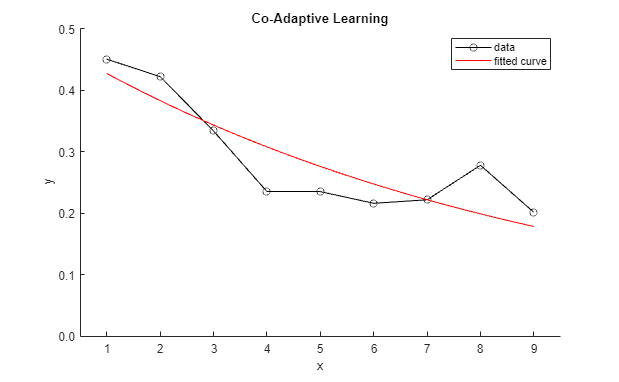

y_coact = y_cond(4, and(y_within.w_task == task, y_within.w_gesture == "Co-Activation"));
y_diffact = y_cond(4, and(y_within.w_task == task, y_within.w_gesture == "Differentiation"));
ax_handle = nexttile;
ax_handle_list = [ax_handle_list, ax_handle];
hold on
% plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
[model_fit, model_gof] = fit((1:9)',y_coact{:,:}',"exp1", 'StartPoint', [0.6, -0.2]);
param_fit_arr = model_fit.b;
plot(model_fit, (1:9)', y_coact{:,:}', '-ko')
hold off
xticks(1:1:9)
xlim([0.5,9.5])
yticks(0:0.1:0.5)
ylim([0, 0.5])
title(task)
ytickformat('%0.1f')

print(fig_h, '../../results/eps-figs/def-rmse', '-depsc', '-r600', '-vector')

### Step 3. Fit Repeated Measures Model

rm = fitrm(y_between, 'y_1-y_54~b_condition', "WithinDesign",y_within)

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [15×55 table]
         ResponseNames: {1×54 cell}
    BetweenFactorNames: {'b_condition'}
          BetweenModel: '1 + b_condition'

   Within Subjects:
          WithinDesign: [54×3 table]
     WithinFactorNames: {'w_task'  'w_gesture'  'w_trial'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [3×54 table]
            Covariance: [54×54 table]


rm.Coefficients

ans = 3×54 table
                          y_1          y_2         y_3          y_4          y_5          y_6          y_7           y_8           y_9          y_10         y_11        y_12         y_13        y_14        y_15         y_16         y_17         y_18        y_19         y_20         y_21          y_22         y_23          y_24          y_25         y_26          y_27         y_28         y_29         y_30         y_31         y_32     

rm.Covariance

ans = 54×54 table
                y_1            y_2           y_3           y_4            y_5            y_6           y_7            y_8           y_9           y_10          y_11          y_12           y_13           y_14           y_15          y_16          y_17          y_18          y_19          y_20         y_21          y_22           y_23          y_24          y_25          y_26           y_27           y_28          y_29           y_30           y_31    

### RANOVA on the Repeated Measures Model

ranova_tbl = ranova(rm, "WithinModel", "w_task + w_trial + w_trial*w_task")

ranova_tbl = 12×8 table
                                   SumSq     DF     MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                  _______    __    ________    ______    __________    __________    __________    __________

    (Intercept)                    74.264     1      74.264    596.36    1.3402e-11    1.3402e-11    1.3402e-11    1.3402e-11
    b_condition                   0.48248     2     0.24124    1.9372        0.1866        0.1866        0.1866        0.1866
    Error                          1.4944    12     0.12453                                                                  
    (Intercept

multcompare(rm, "b_condition")

ans = 6×7 table
    b_condition_1    b_condition_2    Difference     StdErr     pValue       Lower       Upper  
    _____________    _____________    __________    ________    _______    _________    ________

       "hlt"            "par"         -0.058641     0.030372    0.17249     -0.13967    0.022387
       "hlt"            "xpar"        -0.019254     0.030372    0.80464     -0.10028    0.061774
       "par"            "hlt"          0.058641     0.030372    0.17249    -0.022387     0.13967
       "par"            "xpar"         0.039388     0.030372    0.42342     -0.04164     0.12042
       "xpar"           "hlt"          0.019254     0.030372    0.80464    -0.061774     0.10028
       "xpar"           "par"         -0.039388     0.030372    0.

multcompare(rm, "w_task")

ans = 6×7 table
           w_task_1                  w_task_2           Difference     StdErr      pValue        Lower        Upper  
    ______________________    ______________________    __________    ________    _________    _________    _________

    "Co-Adaptive Learning"    "Human Learning"           -0.10646     0.023166    0.0016465     -0.16827    -0.044659
    "Co-Adaptive Learning"    "Machine Learning"        -0.071845     0.019589    0.0083655      -0.1241    -0.019586
    "Human Learning"          "Co-Adaptive Learning"      0.10646     0.023166    0.0016465     0.044659      0.16827
    "Human Learning"          "Machine Learning"         0.034619     0.029848      0.49791    -0.045013      0.11425
    "Machine Learning"        "Co-Ada

multcompare(rm, "w_trial")

ans = 72×7 table
    w_trial_1    w_trial_2    Difference     StdErr      pValue         Lower         Upper  
    _________    _________    __________    ________    _________    ___________    _________

        1            2         0.042057     0.012458     0.087251     -0.0043265      0.08844
        1            3         0.044504     0.019714      0.43039      -0.028893       0.1179
        1            4         0.060824     0.016472     0.052539    -0.00050457      0.12215
        1            5         0.052167     0.020454       0.2973      -0.023985      0.12832
        1            6         0.065279     0.014183     0.011997       0.012476      0.11808
        1            7         0.068028     0.018227     0.049268      0.0001661      

### Export to R

r_dataframe = [];
for i=1:height(y_between)
    if or(y_between{i,1} == "par", y_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([y_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(y_within),1), repmat(y_between{i,1}, height(y_within),1), y_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe

r_dataframe = 810×6 table
      rmse       p_id     p_cond        task_type           gesture_type       trial_num
    _________    _____    ______    __________________    _________________    _________

    "0.42876"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "1"   
    "0.46986"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "2"   
    "0.46987"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "3"   
    "0.41732"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "4"   
    "0.41752"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "5"   
    "0.45718"    "p02"    "par"     "Machine Learning"    "Co-Activation"         "6"   
    "0.39423"    "p02"    "par"     "Machine Learning"   

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
% r_dataframe = convertvars(r_dataframe, ["trial_num"], 'uint16');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 810×6 table
     rmse      trial_num     gesture_type         task_type        p_cond    p_id
    _______    _________    _______________    ________________    ______    ____

    0.42876        1        Co-Activation      Machine Learning     par      p02 
    0.46986        2        Co-Activation      Machine Learning     par      p02 
    0.46987        3        Co-Activation      Machine Learning     par      p02 
    0.41732        4        Co-Activation      Machine Learning     par      p02 
    0.41752        5        Co-Activation      Machine Learning     par      p02 
    0.45718        6        Co-Activation      Machine Learning     par      p02 
    0.39423        7        Co-Activation      Machine Learning     par      p02 
    0.38462        8        Co-

writetable(r_dataframe, '../../temp-data/rdf_rmse_raw_10.csv','WriteMode','overwrite')

### 3-Way ANOVA

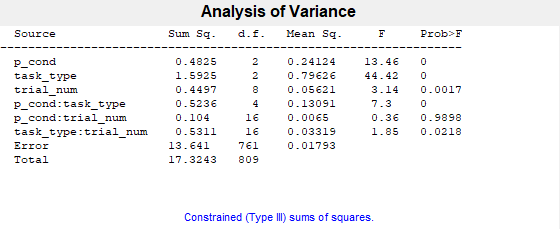

pvals =     0.0000
    0.0000
    0.0017
    0.0000
    0.9898
    0.0218


anova_tbl = 9×7 cell array
    {'Source'             }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'p_cond'             }    {[ 0.4825]}    {[   2]}    {[        0]}    {[  0.2412]}    {[ 13.4584]}    {[1.8035e-06]}
    {'task_type'          }    {[ 1.5925]}    {[   2]}    {[        0]}    {[  0.7963]}    {[ 44.4217]}    {[5.6675e-19]}
    {'trial_num'          }    {[ 0.4497]}    {[   8]}    {[        0]}    {[  0.0562]}    {[  3.1358]}    {[    0.0017]}
    {'p_cond:task_type'   }    {[ 0.5236]}    {[   4]}    {[        0]}    {[  0.1309]}    {[  7.3031]}    {[8.9815e-06]}
    {'p_cond:trial_num'   }    {[ 0.1040]}    {[  16]}    {[        0]}    {[  0.0065]}    {[  0.3625]}    {[    0.9898]}
    {'task_type:trial_num'}    {[ 0.5311]}    {[  16]}    {[        0]}    {[  0.0332]}    {[  1.8518]}    {[    0.0218]}
    {'Error'              }    {[13.6410]}    {[ 761]}    {[        0]}    {[  0.0179]}    {0×0 double}    {0×0 double 

stats = struct with fields:
         source: 'anovan'
          resid: [810×1 double]
         coeffs: [79×1 double]
            Rtr: [49×49 double]
       rowbasis: [49×79 double]
            dfe: 761
            mse: 0.0179
    nullproject: [79×49 double]
          terms: [6×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [7×1 double]
     coeffnames: {79×1 cell}
           vars: [79×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [7×7 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'model',2)

terms(5,:) = []

terms =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     0     1     1


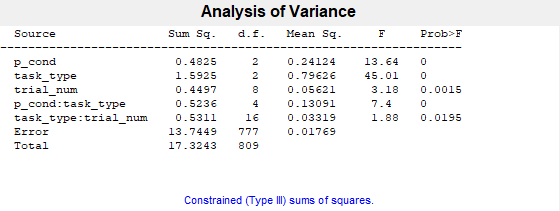

pvals =     0.0000
    0.0000
    0.0015
    0.0000
    0.0195


anova_tbl = 8×7 cell array
    {'Source'             }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }
    {'p_cond'             }    {[ 0.4825]}    {[   2]}    {[        0]}    {[  0.2412]}    {[ 13.6374]}    {[1.5099e-06]}
    {'task_type'          }    {[ 1.5925]}    {[   2]}    {[        0]}    {[  0.7963]}    {[ 45.0126]}    {[3.1859e-19]}
    {'trial_num'          }    {[ 0.4497]}    {[   8]}    {[        0]}    {[  0.0562]}    {[  3.1775]}    {[    0.0015]}
    {'p_cond:task_type'   }    {[ 0.5236]}    {[   4]}    {[        0]}    {[  0.1309]}    {[  7.4002]}    {[7.5013e-06]}
    {'task_type:trial_num'}    {[ 0.5311]}    {[  16]}    {[        0]}    {[  0.0332]}    {[  1.8764]}    {[    0.0195]}
    {'Error'              }    {[13.7449]}    {[ 777]}    {[        0]}    {[  0.0177]}    {0×0 double}    {0×0 double  }
    {'Total'              }    {[17.3243]}    {[ 809]}    {[        0]}    {0×0 double}    {0×0 double}    {0×0 double 

stats = struct with fields:
         source: 'anovan'
          resid: [810×1 double]
         coeffs: [52×1 double]
            Rtr: [33×33 double]
       rowbasis: [33×52 double]
            dfe: 777
            mse: 0.0177
    nullproject: [52×33 double]
          terms: [5×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [6×1 double]
     coeffnames: {52×1 cell}
           vars: [52×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [6×6 double]
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


terms =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     0     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, ...
    {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'model',terms)

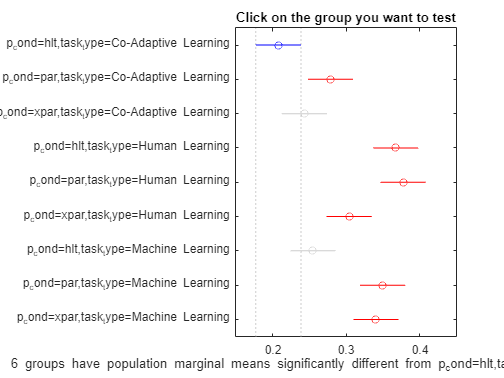

ans =     1.0000    2.0000   -0.1325   -0.0710   -0.0095    0.0103
    1.0000    3.0000   -0.0970   -0.0355    0.0260    0.6879
    1.0000    4.0000   -0.2213   -0.1598   -0.0983    0.0000
    1.0000    5.0000   -0.2313   -0.1698   -0.1083    0.0000
    1.0000    6.0000   -0.1578   -0.0963   -0.0348    0.0000
    1.0000    7.0000   -0.1087   -0.0472    0.0143    0.2956
    1.0000    8.0000   -0.2035   -0.1420   -0.0805    0.0000
    1.0000    9.0000   -0.1944   -0.1329   -0.0714    0.0000
    2.0000    3.0000   -0.0260    0.0355    0.0970    0.6886
    2.0000    4.0000   -0.1503   -0.0888   -0.0273    0.0003


figure
multcompare(stats, "Dimension",[1,2])

### 3-Way ANOVA with Random Effects

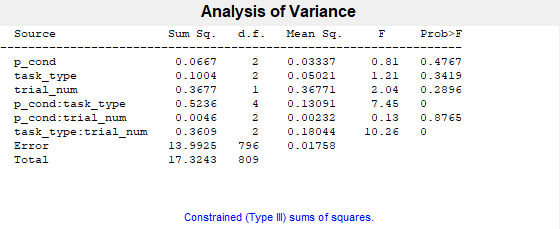

pvals =     0.4767
    0.3419
    0.2896
    0.0000
    0.8765
    0.0000


anova_tbl = 9×15 cell array
    {'Source'             }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }    {'Type'    }    {'Expected MS'                                                                    }    {'MS denom'}    {'d.f. denom'}    {'Denom. defn.'                                    }    {'Var. est.' }    {'Var. lower bnd'}    {'Var. upper bnd'}
    {'p_cond'             }    {[ 0.0667]}    {[   2]}    {[        0]}    {[  0.0334]}    {[  0.8052]}    {[    0.4767]}    {'fixed'   }    {'56.8421*Q(p_cond)+18.9474*V(p_cond:task_type)+V(Error)'                         }    {[  0.0414]}    {[    9.0312]}    {'0.210526*MS(p_cond:task_type)+0.789474*MS(Error)'}    {0×0 double  }    {0×0 double      }    {0×0 double      }
    {'task_type'          }    {[ 0.1004]}    {[   2]}    {[        0]}    {[  0.0502]}    {[  1.2116]}    {[    0.3419]}    {'random'  }    {'56.8421*V(task_type)+18.9474*V(p_cond:task_type)+V(Error)'                 

stats = struct with fields:
         source: 'anovan'
          resid: [810×1 double]
         coeffs: [23×1 double]
            Rtr: [14×14 double]
       rowbasis: [14×23 double]
            dfe: 796
            mse: 0.0176
    nullproject: [23×14 double]
          terms: [6×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 1]
         vmeans: [3×1 double]
       termcols: [7×1 double]
     coeffnames: {23×1 cell}
           vars: [23×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [7×7 double]
          denom: [6×4 double]
        dfdenom: [6×1 double]
        msdenom: [6×1 double]
         varest: [4×1 double]
          varci: [4×2 double]
       txtdenom: {6×1 cell}
         txtems: {7×1 cell}
        rtnames: {4×1 cell}


terms =      1     0     0
     0     1     0
     0     0     1
     1     1     0
     1     0     1
     0     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'random',[2], ...
    'continuous',[3], ...
    'model',2)

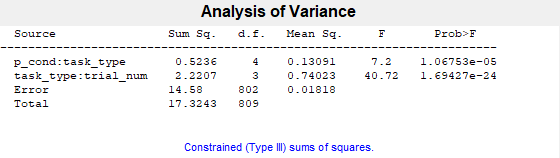

pvals = 1.0e-04 *

    0.1068
    0.0000


anova_tbl = 5×15 cell array
    {'Source'             }    {'Sum Sq.'}    {'d.f.'}    {'Singular?'}    {'Mean Sq.'}    {'F'       }    {'Prob>F'    }    {'Type'    }    {'Expected MS'                            }    {'MS denom'}    {'d.f. denom'}    {'Denom. defn.'}    {'Var. est.' }    {'Var. lower bnd'}    {'Var. upper bnd'}
    {'p_cond:task_type'   }    {[ 0.5236]}    {[   4]}    {[        0]}    {[  0.1309]}    {[  7.2008]}    {[1.0675e-05]}    {'random'  }    {'73.7368*V(p_cond:task_type)+V(Error)'   }    {[  0.0182]}    {[       802]}    {'MS(Error)'   }    {[    0.0015]}    {[    3.6470e-04]}    {[        0.0144]}
    {'task_type:trial_num'}    {[ 2.2207]}    {[   3]}    {[        0]}    {[  0.7402]}    {[ 40.7180]}    {[1.6943e-24]}    {'random'  }    {'1945.16*V(task_type:trial_num)+V(Error)'}    {[  0.0182]}    {[       802]}    {'MS(Error)'   }    {[3.7121e-04]}    {[    1.1179e-04]}    {[        0.0053]}
    {'Error'              }    {[14.5800]}    {[ 802]}    {[        0

stats = struct with fields:
         source: 'anovan'
          resid: [810×1 double]
         coeffs: [13×1 double]
            Rtr: [8×8 double]
       rowbasis: [12×13 double]
            dfe: 802
            mse: 0.0182
    nullproject: [13×8 double]
          terms: [2×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 1]
         vmeans: [3×1 double]
       termcols: [3×1 double]
     coeffnames: {13×1 cell}
           vars: [13×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: [3×3 double]
          denom: [2×3 double]
        dfdenom: [2×1 double]
        msdenom: [2×1 double]
         varest: [3×1 double]
          varci: [3×2 double]
       txtdenom: {2×1 cell}
         txtems: {3×1 cell}
        rtnames: {3×1 cell}


terms =      1     1     0
     0     1     1


[pvals,anova_tbl,stats, terms] = anovan(r_dataframe{:,"rmse"}, {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}, r_dataframe{:,"trial_num"}}, ...
    'varnames',["p_cond", "task_type", "trial_num"], ...
    'random',[2], ...
    'continuous',[3], ...
    'model',terms([4,6],:))

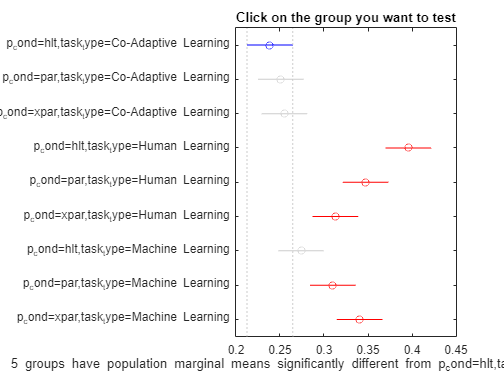

ans =     1.0000    2.0000   -0.0633   -0.0124    0.0385    0.9979
    1.0000    3.0000   -0.0672   -0.0163    0.0346    0.9868
    1.0000    4.0000   -0.2171   -0.1570   -0.0969    0.0000
    1.0000    5.0000   -0.1566   -0.1084   -0.0603    0.0000
    1.0000    6.0000   -0.1224   -0.0743   -0.0261    0.0001
    1.0000    7.0000   -0.0953   -0.0352    0.0249    0.6713
    1.0000    8.0000   -0.1196   -0.0714   -0.0233    0.0001
    1.0000    9.0000   -0.1498   -0.1017   -0.0535    0.0000
    2.0000    3.0000   -0.0548   -0.0039    0.0470    1.0000
    2.0000    4.0000   -0.1928   -0.1446   -0.0965    0.0000


figure
multcompare(stats, 'Dimension',[1,2])

## Helper Functions

function plot_task_data(p_handle, cond_label, task_label, input_ttbl)
tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
ax_list = [];
for t = 1:9
    trial_label = sprintf("Trial %02d", t);
    trial_ttbl = extract_segment(input_ttbl, trial_label, task_label);
    trmse_coact = compute_gesture_metric(trial_ttbl, "trmse", "Co-Activation");
    trmse_diffact = compute_gesture_metric(trial_ttbl, "trmse", "Differentiation");
    ax = nexttile;
    ax_list = [ax_list, ax];
    title(trial_label)
    subtitle(sprintf("Co-Act:%.3f\t Diff Act:%.3f", trmse_coact, trmse_diffact))
    hold on
    plot(trial_ttbl.Time, trial_ttbl.("Targets"), "LineWidth", 3, "LineStyle", ":")
    ax.ColorOrderIndex = 1;
    plot(trial_ttbl.Time, trial_ttbl.("Kalman"), "LineWidth", 3)
    yline([-0.1, 0.1]+0.5, 'r--')
    yline([-0.1, 0.1]+0.0, 'k--')
    hold off
    box off
end
linkaxes(ax_list, 'y')
ylim([-0.25, 1])
set(ax_list, 'FontSize', 18)
title(tlo, sprintf("%s - %s - %s", p_handle.participant_id, upper(cond_label), upper(task_label)))
end

function [fig_handle] = plot_bounded_fit(x, y, ax_handle, y_color)
y_fit = fit(x, y, 'poly1');
y_bounds = predint(y_fit, x, 0.95, 'functional', 'on');
x_conf = [x' flip(x')];
y_conf = [y_bounds(:,2)' flip(y_bounds(:,1)')];
hold on
rgb_color = convertStringsToChars(y_color);
rgb_color = reshape(sscanf(rgb_color(2:end), '%2x') / 255, [], 3);
p = fill(ax_handle, x_conf, y_conf, rgb_color);
p.FaceColor = [rgb_color];
p.FaceAlpha = 0.5;
p.EdgeColor = 'none';
plot(ax_handle, x, y_bounds, '--', 'Color',y_color); xlim ([0 10]); ylim([0 0.8]);
plot(ax_handle, x, [y, feval(y_fit, x)], 'Color', y_color);
hold off
end